# Fixed-Point Multiplication

In general, a full precision product requires a word length equal to the sum of the word lengths of the operands. 

 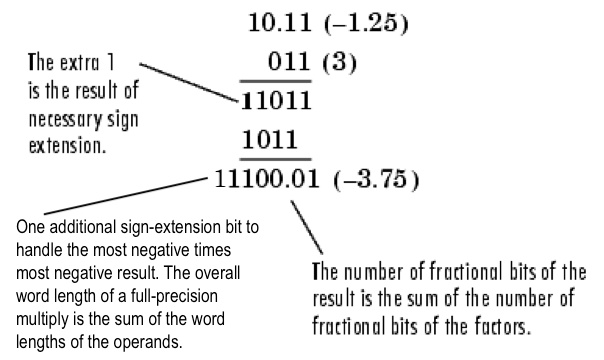

In the following example, note that the word length of the product $c$ is equal to the word length of $a$ plus the word length of $b$. The fraction length of $c$ is also equal to the fraction length of $a$ plus the fraction length of $b$.

a = fi(-1.25,1,4,2)

a =   -1.250000000000000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 4
        FractionLength: 2

a.bin

ans = '1011'


b = fi(3,1,3,0)

b =      3

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 3
        FractionLength: 0

b.bin

ans = '011'


c = a * b

c =   -3.750000000000000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 7
        FractionLength: 2

c.bin

ans = '1110001'

## C code generation

codegen mytimes -args {a,b} -config:lib -launchreport

Code generation successful: View report



## HDL code generation

codegen mytimes -args {a,b} -config:hdl -launchreport


### Begin VHDL Code Generation
### Working on mytimes as mytimes.vhd.
### Generating Resource Utilization Report resource_report.html.
### Generating HDL Conformance Report mytimes_hdl_conformance_report.html.
### HDL Conformance check complete with 0 errors, 0 warnings, and 0 messages.
### Code generation successful: 

## SystemC code generation

cfg = coder.HdlConfig;
cfg.TargetLanguage = "SystemC";
codegen mytimes -args {a,b} -config cfg -launchreport


### Begin SystemC Code Generation
### Working on mytimesClass.hpp as mytimesClass.hpp.
### Working on mytimesModule.hpp as mytimesModule.hpp.
### Generating HDL Conformance Report mytimes_hdl_conformance_report.html.
### HDL Conformance check complete with 0 errors, 0 warnings, and 0 messages.
### Code generation successful: 